# MEMS 1052 Homework 1

## Problem 1

Given: $L=50\:mm=50(10^{-3})\:m
$, $q^"=40\:\frac{W}{m^2}$, $T_H=40\:^oC$, $T_C=20\:^oC$

Heat flux equation:  $q^"=k\left(-\frac{dT}{dx}\right)$

Temperature profile for 1D conduction through a plane wall (assume steady state):  $T(x)=(T_C-T_H)\frac{x}{L}+T_H$


$$-\frac{dT}{dx}=-\frac{(T_C-T_H)}{L}=\frac{T_H-T_C}{L}$$


Substituting this back into the heat flux equation, we can solve for K and plug in known values:


$$q^"=k\left(\frac{T_H-T_C}{L}\right)$$



$$k=\frac{q^"L}{T_H-T_C}=\frac{(40\:W/m^2)(0.05\:m)}{40-20\:^oC}$$



$$\mathbf{k=0.1\:\frac{W}{m*K}}$$


## Problem 2

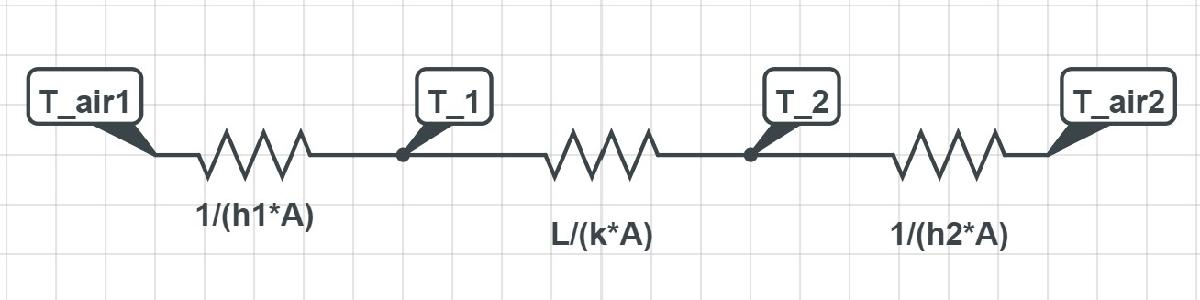

Given: $T_{\infty,1}=20\:^oC$, $T_1=16\:^oC$, $T_2=6\:^oC$, $T_{\infty,2}=5\:^oC$, $h_1=5\:\frac{W}{m^2K}$, $h_2=20\:\frac{W}{m^2K}$

Heat flux from interior air to wall:


$$q_{\infty1\rightarrow w}=q_{\infty1\rightarrow w}^"*A=h_1A(T_{\infty,1}-T_1)$$



$$q_{\infty1\rightarrow w}^"=h_1(T_{\infty,1}-T_1)$$


% calculate heat flux from interior air to wall
T_air1 = 20; % deg C
T_1 = 16; % deg C
h1 = 5; % W/(m^2*K)

flux1 = h1*(T_air1-T_1);
fprintf('The heat flux from the interior air to the wall is %d [W/m^2].',flux1)

The heat flux from the interior air to the wall is 20 [W/m^2].

Heat flux from wall to exterior air:


$$q_{w\rightarrow\infty2}=q_{w\rightarrow \infty2}^"*A=h_2A(T_2-T_{\infty,2})$$



$$q_{w\rightarrow \infty2}^"=h_2(T_2-T_{\infty,2})$$


% calculate heat flux from wall to exterior air
T_2 = 6; % deg C
T_air2 = 5; % deg C
h2 = 20; % W/(m^2*K)

flux2 = h2*(T_2-T_air2);
fprintf('The heat flux from the wall to the exterior air is %d [W/m^2].',flux2)

The heat flux from the wall to the exterior air is 20 [W/m^2].

Heat flux from wall to interior air:


$$q_{w\rightarrow\infty1}=q_{w\rightarrow \infty1}^"*A=h_1A(T_1-T_{\infty,1})$$



$$q_{w\rightarrow \infty1}^"=h_1(T_1-T_{\infty,1})=-q_{\infty1\rightarrow w}^"$$



$$\therefore \mathbf{q_{w\rightarrow \infty1}^"=-20\:\left[\frac{W}{m^2}\right]}$$


Yes, the wall is under steady state conditions since the heat flux throughout the system is equal.

## Problem 3

Assume steady state 1D conduction in a plane wall with no internal heat generation.

Given: $L=0.35\:m$, $k=50\:\frac{W}{m*K}$

Temperature profile across wall:  

$T(x)=(T_C-T_H)\frac{x}{L}+T_H=\frac{(T_C-T_H)}{L}x+T_H$    (1)

$-\frac{dT}{dx}=-\left(\frac{T_C-T_H}{L}\right)=\left(\frac{T_1-T_2}{L}\right)$    (2)

Heat flux equation:

$q^"=k\left(-\frac{dT}{dx}\right)=k\left(\frac{T_H-T_C}{L}\right)=k\left(\frac{T_1-T_2}{L}\right)$    (3)

**For this problem, we are initially assuming $T_H=T_1$ and $T_C=T_2$ for all cases to keep the signs consistent.

p3_newtable = p3_table;
p3_table

p3_table = 5×4 table
    Case    T1 [deg C]    T2 [deg C]    dT/dx [K/m]
    ____    __________    __________    ___________

     1          50           -20              0    
     2         -30           -10              0    
     3          70             0            160    
     4           0            40            -80    
     5           0            30            200    


% establish givens
L = 0.35; % [m]
k = 50; % [W/m^2]

To calculate $\frac{dT}{dx}$ for cases 1 and 2, we can use equation (2):    $-\frac{dT}{dx}=\frac{T_1-T_2}{L}$

% calculate dT/dx for case 1,2
p3_newtable{1,4}=(p3_newtable{1,3}-p3_newtable{1,2})/L;
p3_newtable{2,4}=(p3_newtable{2,3}-p3_newtable{2,2})/L;

To calculate $T_2$ for case 3, we can rearrange equation (2) to solve for $T_2$:    $T_2=L\frac{dT}{dx}+T_1$

% calculate T2 for case 3
p3_newtable{3,3}=L*p3_newtable{3,4}+p3_newtable{3,2};

To calculate $T_1$ for cases 4 and 5, we can rearrange equation (2) to solve for $T_1$:    $T_1=T_2-L\frac{dT}{dx}$

% calculate T1 for case 4,5
p3_newtable{4,2}=p3_newtable{4,3}-(L*p3_newtable{4,4});
p3_newtable{5,2}=p3_newtable{5,3}-(L*p3_newtable{5,4});

To calculate $q"$ for all cases, we can use equation (3):    $q^"=k\left(\frac{T_1-T_2}{L}\right)$

% calculate q" for all cases
i=1;
flux=[0;0;0;0;0];
while i<6
    flux(i,1) = k*(-p3_newtable{i,4});
    i=i+1;
end

p3_newtable.('Heat Flux [W/m^2]') = flux;

p3_newtable

p3_newtable = 5×5 table
    Case    T1 [deg C]    T2 [deg C]    dT/dx [K/m]    Heat Flux [W/m^2]
    ____    __________    __________    ___________    _________________

     1          50           -20            -200              10000     
     2         -30           -10          57.143            -2857.1     
     3          70           126             160              -8000     
     4          68            40             -80               4000     
     5         -40            30             200             -10000     


#### 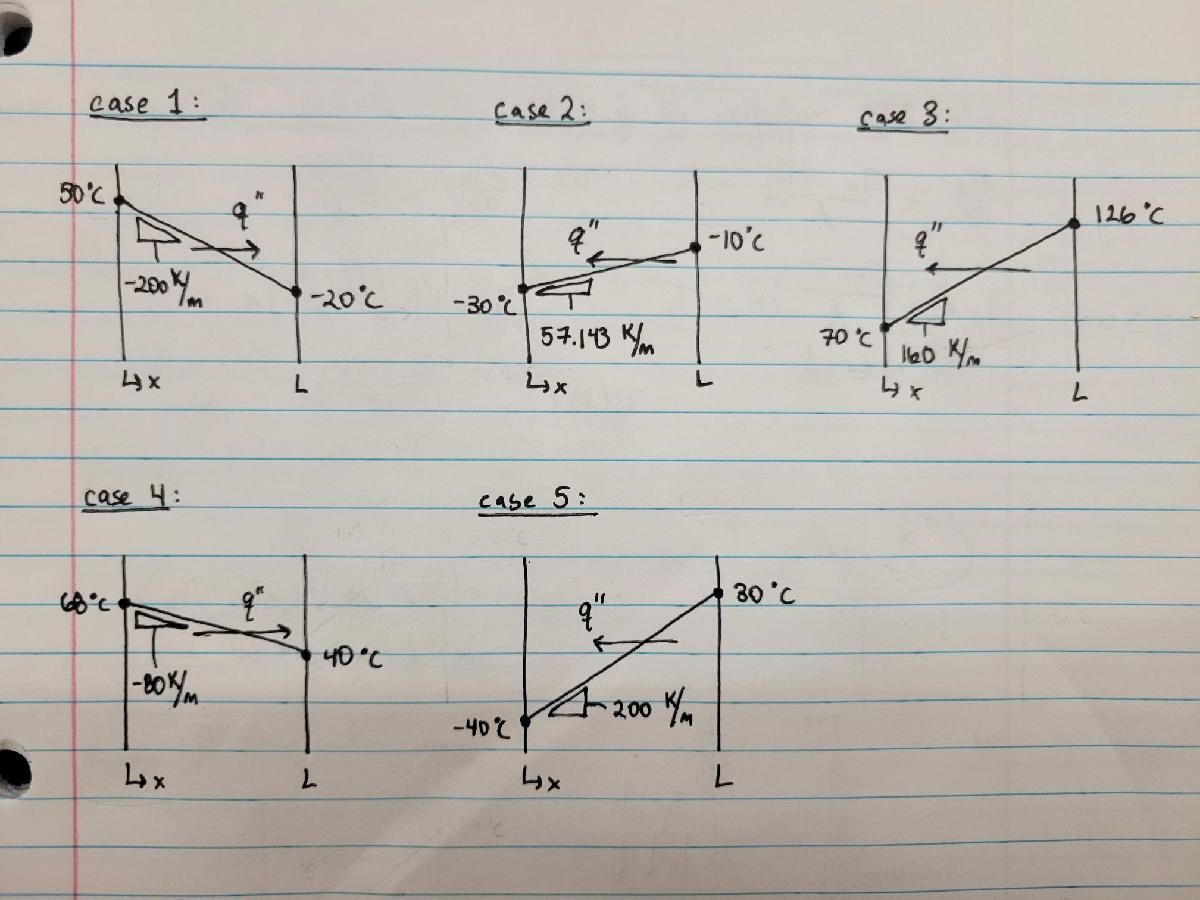

## Problem 4

Given that $T_1<T_2$ and $k_A=0.5k_B$, the temperature and heat flux distributions across the composite bar are portrayed approximately in the diagrams below.

Temperature Distribution:

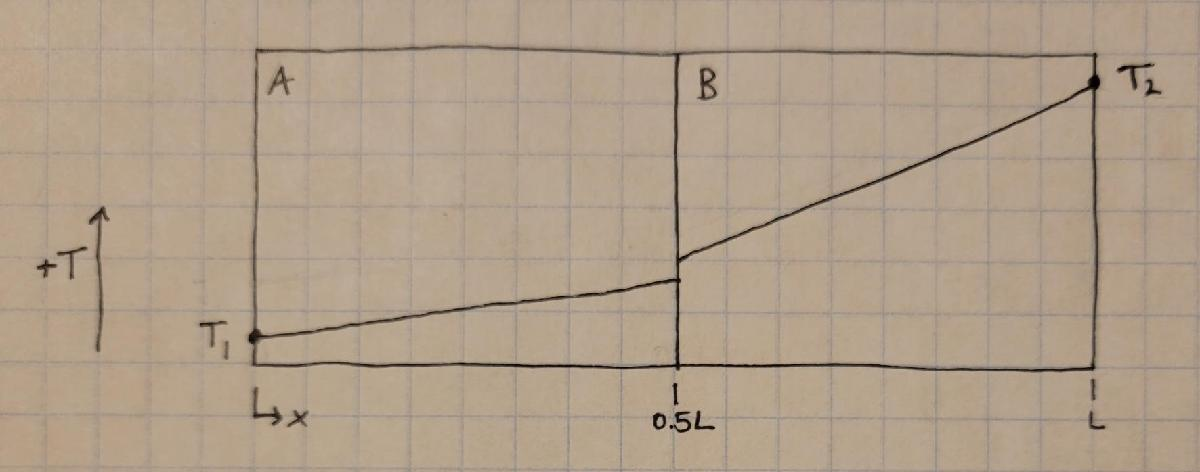

Heat Flux Distribution:

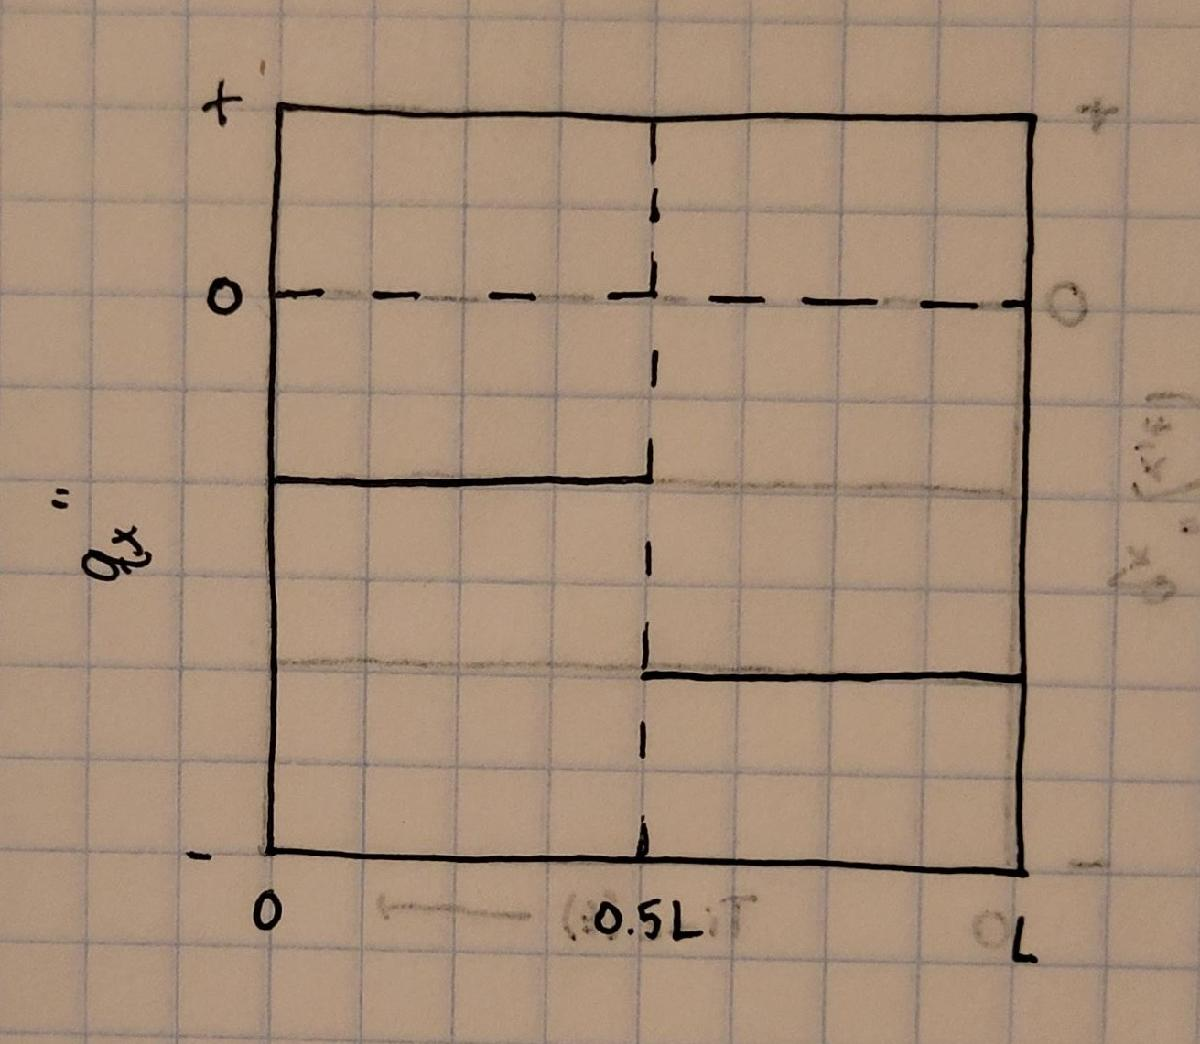

## Problem 5

### Part (a)

Start with the general heat diffusion equation and assume 1D conduction through a plane wall with constant properties and no internal heat generation.


$$\rho C\frac{\delta T}{\delta t}=k\left(\frac{\delta^2T}{\delta x^2}+\frac{\delta^2T}{\delta y^2}+\frac{\delta^2T}{\delta z^2}\right)+q_{gen}$$



$$\mathbf{\rho C\frac{\delta T}{\delta t}=k\left(\frac{\delta^2T}{\delta x^2}\right)}$$


Initial conditions:

Uniform temperature for $t\le0$:    $T(x,0)=T_i$

Boundary conditions ($t>0$):

Adiabatic at $x=0$:    $\frac{\delta T}{\delta x}(0,t)=0$

Convective surface at $x=L$:    $-\frac{\delta T}{\delta x}|_{x=L}=\frac{h}{k}\left(T_{\infty}-T_{(L,t)}\right)$

### Part (b)

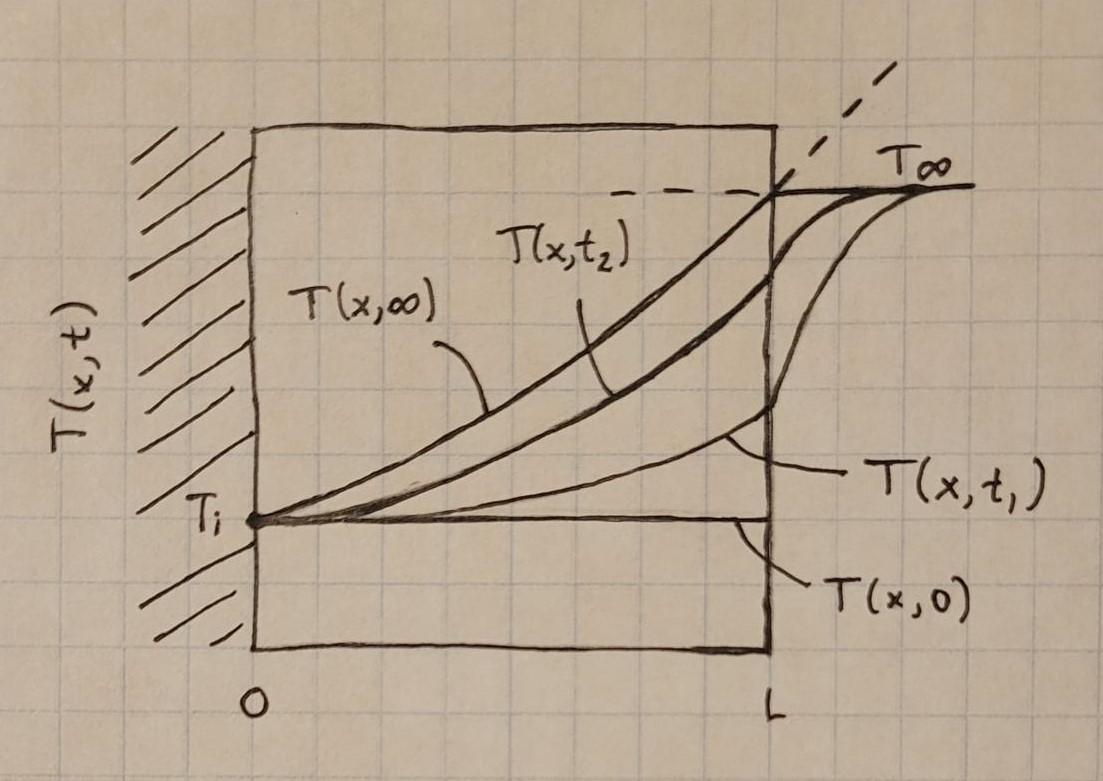

### Part (c)

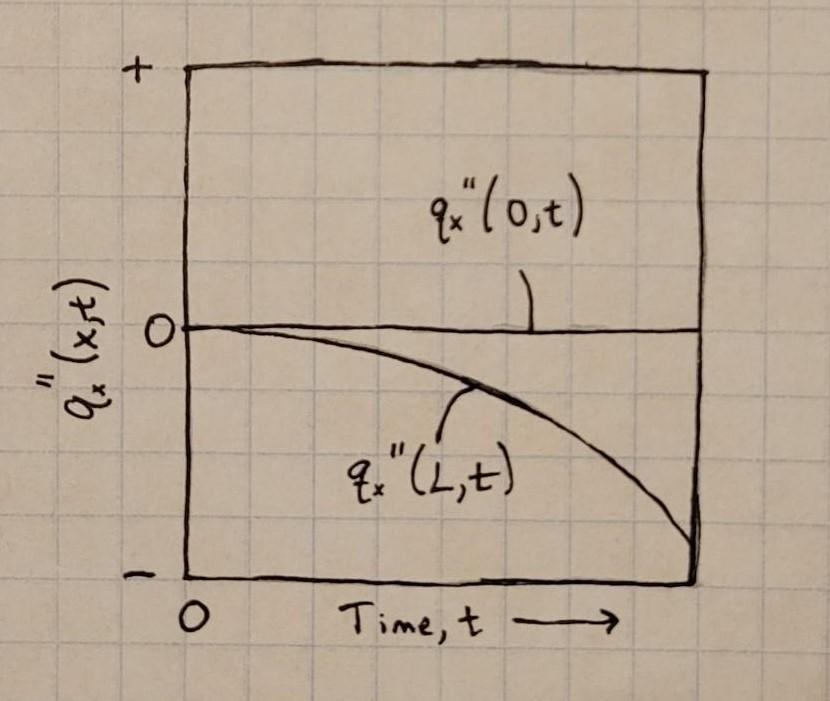

### Part (d)

To get an expression for the the energy transferred to the wall per unit volume, we can start with the heat flow into the wall, which has units of Watts, or $\frac{J}{s}$. To find the energy in $\frac{J}{m^3}$, we just need to multiply by time and divide by the volume.

Energy transferred to wall (per unit volume):    $\frac{E}{V}=\frac{q_xt}{AL}=\frac{k\left(-\frac{dT}{dx}\right)t}{L}$